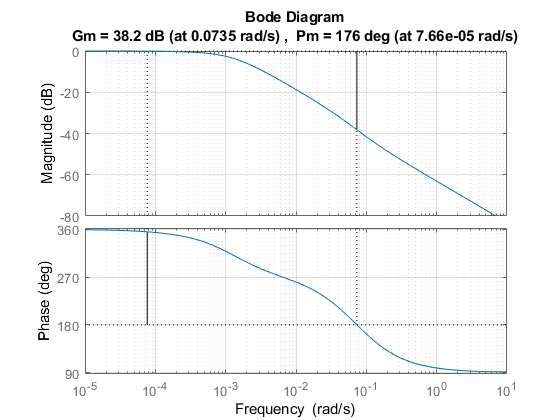

clear all, close all, clc

%%%% Método Ziegler–Nichols %%%%%
s=tf('s');

P=(-0.0006973*s^2 + 6.56e-05*s + 1.391e-08)/(s^3 + 0.05674*s^2 + 7.965e-05*s + 1.381e-08); %Planta 2 pólos complexos e polo em zero 

figure, margin(P), grid %Critério de estabilidade no dominio da frequência

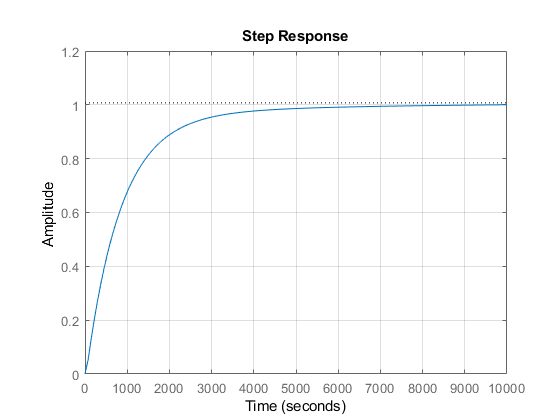


figure, step(P,10000), grid %comportamento temporal malha aberta


P=feedback(P,1) % Malha fechada


P =
 
    -0.0006973 s^2 + 6.56e-05 s + 1.391e-08
  -------------------------------------------
  s^3 + 0.05604 s^2 + 0.0001452 s + 2.772e-08
 
Continuous-time transfer function.



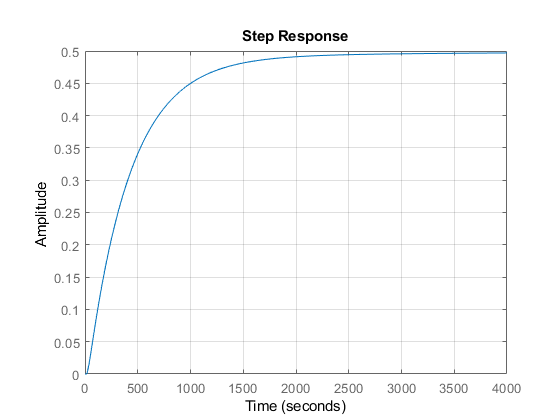


step(P),grid % comportamento temporal malha fechada




%Para calcular os valores de Kp,Kd e Ki devo usar Km e Wm do diagrama de bode 
[Km,Pm,Wm,Wcp] = margin(P) 

Km = 80.0682

Pm = Inf

Wm = 0.0735

Wcp = NaN

%k1=14.905
%P1=k1*P
% P1=feedback(P1,1)
%step(P1),grid

kp=0.6*Km

kp = 48.0409

kd=kp*pi/4/Wm

kd = 513.5647

ki=kp*Wm/pi

ki = 1.1235


% ki=5;
% kp=4;
% kd=0.8;

K=kd*s+kp+ki/s;

pid(K)


ans =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 48, Ki = 1.12, Kd = 514
 
Continuous-time PID controller in parallel form.




LA=K*P;

T=feedback(LA,1); %sistema realimentado de control com PID
damp(T)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -2.12e-04                 1.00e+00       2.12e-04         4.73e+03    
 -1.65e-02 + 4.29e-02i     3.58e-01       4.60e-02         6.07e+01    
 -1.65e-02 - 4.29e-02i     3.58e-01       4.60e-02         6.07e+01    
 -5.44e-02                 1.00e+00       5.44e-02         1.84e+01    


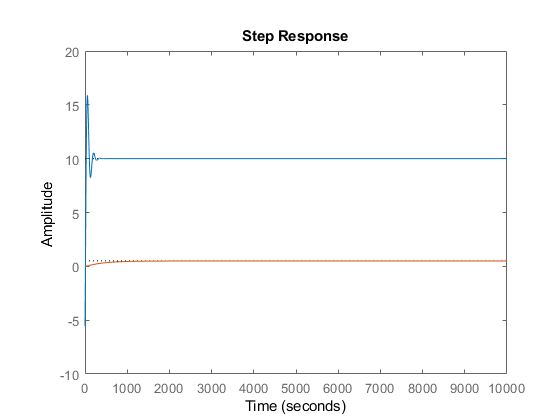

% Para mostrar as dois respostas coloco 10 vezes T
figure, step(10*T,10000), grid
hold on 
step(P,10000),grid